## Test the behavior of the makeChemostat function.

Define a value D = medium flow rate / culture volume

Desired behavior:

- All present external metabolites are removed at a rate of D% per hour

- At steady state, the specific growth rate of microorganisms is equal to D

-     If the growth rate of an organism < D, it should wash out

-     If the initial growth rate of an organism > D, the rate should decrease based on availability of some nutrient until steady state is reached

- A metabolite that does not interact with the microorganism should stay at its initial concentration

-     Similarly, metabolites consumed by the microorganism should always be <= initial concentration, and produced metabolites should be >= intitial concentration

- Results should not be affected by timestep length

- Dilution rate input is in units of volume/hour

## Test dilution and media refresh behavior

Define 3 metabolites

- "constant" should remain at its initial concentration (1mmol)

- "accumulate" is manually removed from the medium at start, and should build up to approach its defined concentration in the media recipe (2mmol)

- "deplete" is manually added to the medium at the start (2mmol), and should approach 0

layout = createLayout();
layout.params.maxCycles = 600;
%add a dummy model
model = createModel();
model = addReaction(model,'rxn',{'met1' 'met2'},[-1 1]);
model = addExchangeRxn(model,{'met1' 'met2'});
model.c = 1;
layout = addModel(layout,model);

%add the media names
layout = addMets(layout,{'accumulate' 'constant' 'deplete'});

%set the recipe
layout = setInitialMedia(layout,'constant',1);
layout = setInitialMedia(layout,'accumulate',2);

%make Chemostat
%flow rate = 10mL/h, volume = 10mL
layout = makeChemostat(layout,10,10);

%perturb the initial state
layout = setInitialMedia(layout,'accumulate',0);
layout = setInitialMedia(layout,'deplete',2);

%run COMETS
layout.params.writeMediaLog = true;
currentFile = which('testMakeChemostat');
[pathstr,~,~] = fileparts( currentFile );
runComets(layout,[pathstr '/out']);

Executing COMETS in the directory C:\sync\biomes\scripts\CometsToolbox\test\out


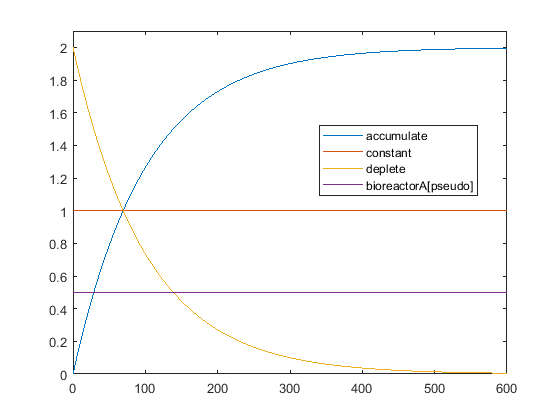

media = parseMediaLog([pathstr '/out/' layout.params.mediaLogName]);

%plot results
plotMediaTimecourse(media,{'accumulate' 'constant' 'deplete' 'bioreactorA[pseudo]' 'bioreactorB[pseudo]'});
ylim([0,2.1]);